# Problema 1

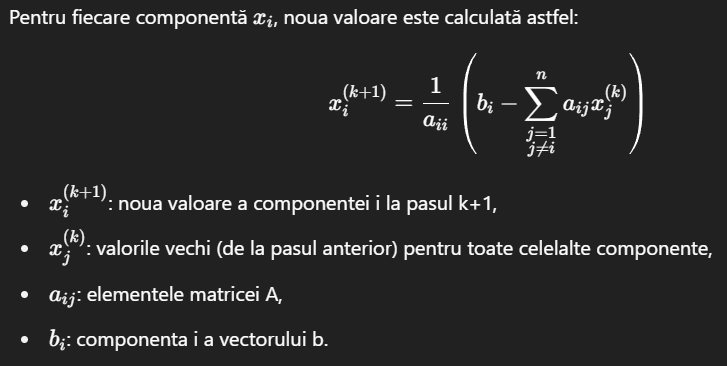

% Pentru a rezolva sistemul Ax=b

function [aprox, num_iteratii] = metoda_jacobi(A, b, tol, iter_max)
    n = size(A, 1);                  % numarul de necunoscute (lungimea vectorului x)
    x_vechi = zeros(n, 1);           % vectorul x^(k) — initializat cu 0
    aprox = zeros(n, 1);             % vectorul x^(k+1) — solutia curenta
    num_iteratii = 0;                % contorul de iteratii

    while num_iteratii < iter_max
        for i = 1:n
            suma = 0;
             % Calculam suma a_jk * x_k pentru j ≠ i
            for j = 1:n
                if j ~= i
                    suma = suma + A(i,j) * x_vechi(j);
                end
            end
            % Actualizam componenta i a noii soluții
            aprox(i) = (b(i) - suma) / A(i,i);
        end

        % Daca norma infinita a diferentei intre doua iteratii succesive
        % este mica
        if norm(aprox - x_vechi, inf) < tol
            % iesim daca am atins precizia dorita
            break;
        end

        x_vechi = aprox;
        num_iteratii = num_iteratii + 1;
    end
end

function verifica_solutie(A, b, x)
    if norm(A*x - b, inf) < 1e-6
        disp('Solutia este valida (Ax ≈ b).');
    else
        disp('Solutia NU este corecta.');
    end
end

A = [5 -1 0; 
    -1 5 -1; 
    0 -1 5];
b = [4; 3; 4];
toleranta = 1e-6;   % acesta sa fie nivelul de precizie (folosit la oprirea iteratiilor)
iteratii_maxime = 100;

[x_final, nr_iter] = metoda_jacobi(A, b, toleranta, iteratii_maxime);
fprintf('Solutie aproximativa dupa %d iteratii:\n', nr_iter);

Solutie aproximativa dupa 12 iteratii:


disp(x_final);

    1.0000
    1.0000
    1.0000




verifica_solutie(A, b, x_final);

Solutia este valida (Ax ≈ b).
